依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

长时间相同光水任务的热图

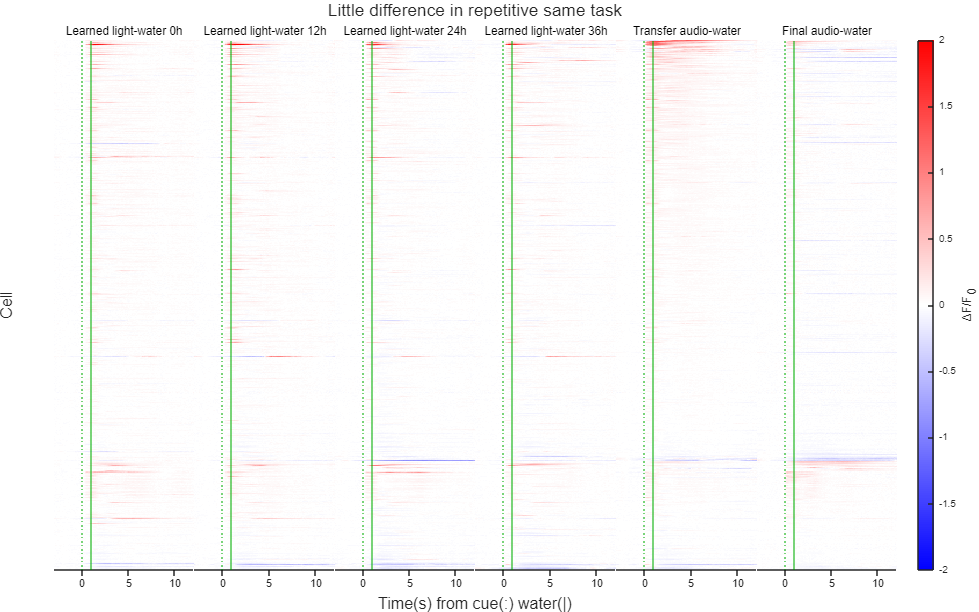

Impl(TransferLearning.Flags.LightAudio|TransferLearning.Flags.PPT);

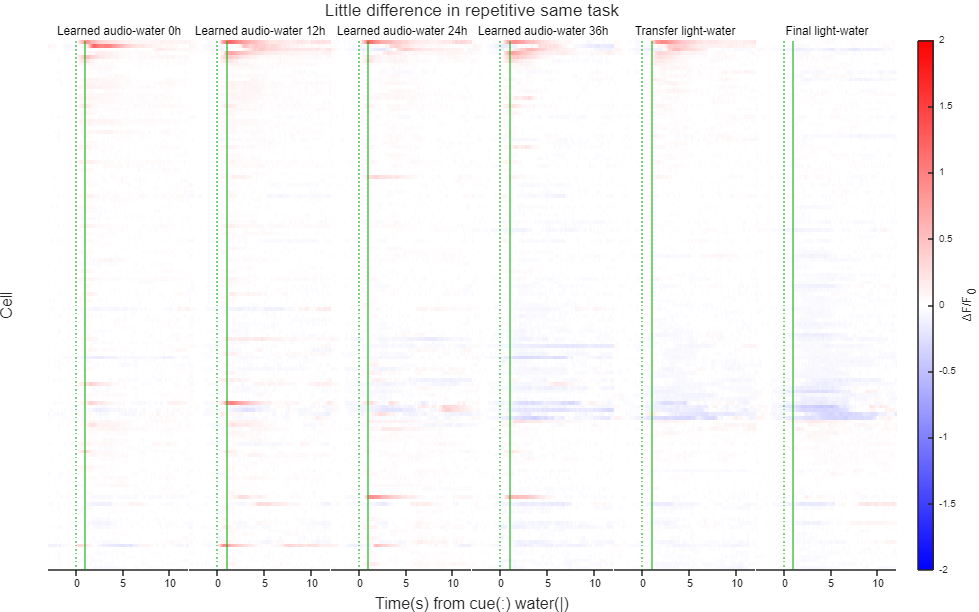

Impl(TransferLearning.Flags.AudioLight|TransferLearning.Flags.PPT);

function Impl(FigureFlag)
import TransferLearning.*
switch FigureFlag&Flags.Paradigm
	case Flags.LightAudio
		SheetName='光声持续训练';
		SubTitles=["Learned light-water 0h","Learned light-water 12h","Learned light-water 24h","Learned light-water 36h","Transfer audio-water","Final audio-water"];
	case Flags.AudioLight
		SheetName='声光持续训练';
		SubTitles=["Learned audio-water 0h","Learned audio-water 12h","Learned audio-water 24h","Learned audio-water 36h","Transfer light-water","Final light-water"];
	otherwise
		Exception.Unsupported_paradigm.Throw;
end
GroupNtats=NtatsFromSheetname(SheetName,Flags.Different_cells_stripped);
Layout=BasicHeatmap(UniExp.HeatmapSort(GroupNtats,["Transfer","Final"],'descend').NTATS{:,:,["Learned_0h","Learned_12h","Learned_24h","Learned_36h","Transfer","Final"]},SubTitles,GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]),false,CLim=[-2,2]);
MATLAB.Graphics.FigureAspectRatio(8,5,2);
Target=Flags(FigureFlag&Flags.Target);
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp %u cells %u mice',height(GroupNtats),numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,GroupNtats.CellUID))))));
	case Flags.PPT
		title(Layout,'Little difference in repetitive same task');
	otherwise
		Exception.Unsupported_target.Throw;
end
print(ProjectPath(sprintf('%s.%s.svg',SheetName,Target)),'-dsvg');
end